# 1

%% 1. 데이터 로드 및 기본 정보 확인
clear; clc;
load(['0317_23ICA_epochedEEG.mat']); % 데이터 불러오기

N = length(epochedEEG); % 에포크 개수
fs = 125; % 샘플링 주파수

fprintf('총 %d개의 에포크가 로드됨\n', N);

총 120개의 에포크가 로드됨


disp(size(epochedEEG{1})); % M × 16 확인

   375    15



disp(labels{1}); % 첫 번째 에포크 라벨

Hello



%% 2. 필터링 (1~50Hz Bandpass)
low_cutoff = 1; 
high_cutoff = 50;
order = 4; 

[b, a] = butter(order, [low_cutoff high_cutoff] / (fs/2), 'bandpass');

for i = 1:N
    epochedEEG{i} = filtfilt(b, a, epochedEEG{i});
end
disp('필터링 완료.');

필터링 완료.



%% 전처리된 데이터 저장
save('preprocessedEEG.mat', 'epochedEEG', 'labels');
disp('전처리된 데이터 저장 완료.');

전처리된 데이터 저장 완료.


for i = 1:N
    disp(size(epochedEEG{i})); % 각 epoch의 크기 출력
end

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15

   375    15



%% 1. 데이터 로드
clear; clc;
load('0317_24ICA_epochedEEG.mat');

epochedEEG = epochedEEG(1:2:end); 
labels = labels(1:2:end);

N = length(epochedEEG);
fs = 125; % 샘플링 주파수

%% 2. 공분산 행렬 특징 (Spatial Features)
feature_matrix = [];
label_vector = [];

for i = 1:N
    epoch = epochedEEG{i};  
    cov_mat = cov(epoch); 
    feature_vector = cov_mat(triu(true(size(cov_mat)))); 
    feature_matrix = [feature_matrix; feature_vector(:)']; 
    label_vector = [label_vector; labels{i}];
end
disp('공분산 행렬 특징 추출 완료.');

공분산 행렬 특징 추출 완료.



%% 3. 파워 스펙트럼 밀도 (PSD)
psd_features = [];

for i = 1:N
    epoch = epochedEEG{i};
    psd_epoch = [];
    
    for ch = 1:16
        [pxx, f] = pwelch(epoch(:, ch), [], [], [], fs);
        psd_epoch = [psd_epoch; pxx]; 
    end
    
    psd_epoch = psd_epoch(:)'; 
    psd_features = [psd_features; psd_epoch];
end
disp('PSD 특징 추출 완료.');

PSD 특징 추출 완료.



%% 4. 시간 도메인 특징 (Mean, Std, Energy)
time_features = [];

for i = 1:N
    epoch = epochedEEG{i};
    mean_vals = mean(epoch, 1);
    std_vals = std(epoch, 1);
    energy_vals = sum(epoch.^2, 1);
    
    feature_vector = [mean_vals, std_vals, energy_vals];
    time_features = [time_features; feature_vector];
end
disp('시간 도메인 특징 추출 완료.');

시간 도메인 특징 추출 완료.



%% 5. 모든 특징 결합 및 저장
final_features = [feature_matrix, psd_features, time_features];

[label_classes, ~, label_vector_num] = unique(label_vector);

save('featuresEEG.mat', 'final_features', 'label_vector_num', 'label_classes');
disp('특징 저장 완료.');

특징 저장 완료.


%% 1. 데이터 로드
clear; clc;
load('featuresEEG.mat');

%% 2. SVM 모델 훈련
SVMModel = fitcecoc(final_features, label_vector_num); 
disp('SVM 모델 훈련 완료.');

SVM 모델 훈련 완료.



%% 3. 10-fold 교차 검증
cv = crossval(SVMModel, 'KFold', 10);
accuracy = 1 - kfoldLoss(cv);
fprintf('SVM 10-fold 교차 검증 정확도: %.2f%%\n', accuracy * 100);

SVM 10-fold 교차 검증 정확도: 25.00%


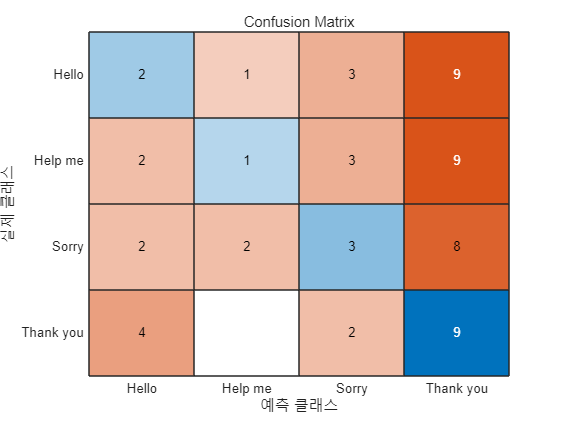


%% 4. Confusion Matrix 출력
predicted_labels = kfoldPredict(cv);
conf_mat = confusionmat(label_vector_num, predicted_labels);
conf_chart = confusionchart(conf_mat, label_classes);
title('Confusion Matrix');

# 2


%% 1. 데이터 로드 및 기본 설정
clear; clc;
load('0317_2ICA_epochedEEG.mat'); % 전처리된 EEG 데이터 불러오기

epochedEEG = epochedEEG(1:2:end); 
labels = labels(1:2:end);

N = length(epochedEEG); 
labels = string(labels); % 셀 배열을 문자열 벡터로 변환
classes = unique(labels); % 고유한 클래스 추출
num_classes = length(classes);
fs = 125; % 샘플링 주파수

%% 2. CSP 적용을 위한 One-vs-One (OvO) 조합 생성
combinations = nchoosek(1:num_classes, 2); % 클래스 쌍 조합
num_pairs = size(combinations, 1);
csp_features = [];

%% 3. 각 클래스 쌍에 대해 CSP 적용
for pair = 1:num_pairs
    % 현재 비교할 클래스 선택
    class1 = classes(combinations(pair,1));
    class2 = classes(combinations(pair,2));
    
    % 해당 클래스 데이터 추출
    idx1 = find(labels == class1);
    idx2 = find(labels == class2);
    
    data1 = cat(3, epochedEEG{idx1});
    data2 = cat(3, epochedEEG{idx2});
    
    % 공분산 행렬 계산
    cov1 = cov(mean(data1, 3));
    cov2 = cov(mean(data2, 3));
    
    % 공분산 행렬의 고유값 분해
    [V, D] = eig(cov1 + cov2);
    
    % 정렬하여 CSP 변환 행렬 생성
    [~, order] = sort(diag(D), 'descend');
    W = V(:, order);
    
    % 필터 개수 자동 조정
    num_eigenvectors = size(W, 2);
    num_filters = min(3, floor(num_eigenvectors / 2));
    selected_indices = [1:num_filters, num_eigenvectors-num_filters+1:num_eigenvectors];
    W_selected = W(:, selected_indices);


    % 각 에포크에 대해 CSP 변환 후 특징 추출
    csp_transformed = [];

    for i = 1:N
        transformed_epoch = W_selected' * epochedEEG{i}';
        var_features = log(var(transformed_epoch, 0, 2)); % 로그 분산 특징
        csp_transformed = [csp_transformed; var_features'];
    end

    csp_features = [csp_features, csp_transformed];
end

disp('CSP 변환 완료.');

CSP 변환 완료.



%% 4. 라벨을 숫자로 변환
[label_classes, ~, label_vector_num] = unique(labels);

%% 5. 다중 클래스 SVM 훈련
SVMModel = fitcecoc(csp_features, label_vector_num);
disp('CSP 기반 SVM 모델 훈련 완료.');

CSP 기반 SVM 모델 훈련 완료.



%% 6. 20-fold 교차 검증
cv = crossval(SVMModel, 'KFold', 20);

accuracy = 1 - kfoldLoss(cv);
fprintf('CSP 기반 SVM 20-fold 교차 검증 정확도: %.2f%%\n', accuracy * 100);

CSP 기반 SVM 20-fold 교차 검증 정확도: 20.00%



%% 7. Confusion Matrix 출력
predicted_labels = kfoldPredict(cv);
conf_mat = confusionmat(label_vector_num, predicted_labels);
conf_chart = confusionchart(conf_mat, label_classes);
title('CSP 기반 Confusion Matrix');


# 3

%% 1. 데이터 로드 및 기본 설정
clear; clc;
load('0317_24ICA_epochedEEG.mat'); % 전처리된 EEG 데이터 불러오기

epochedEEG = epochedEEG(1:2:end); 
labels = labels(1:2:end);

N = length(epochedEEG); 
labels = string(labels); % 셀 배열을 문자열 벡터로 변환
classes = unique(labels); % 고유한 클래스 추출
num_classes = length(classes);
fs = 125; % 샘플링 주파수

%% 2. CSP 적용을 위한 One-vs-One (OvO) 조합 생성
combinations = nchoosek(1:num_classes, 2); % 클래스 쌍 조합
num_pairs = size(combinations, 1);
csp_features = [];

%% 3. 각 클래스 쌍에 대해 CSP 적용
for pair = 1:num_pairs
    % 현재 비교할 클래스 선택
    class1 = classes(combinations(pair,1));
    class2 = classes(combinations(pair,2));
    
    % 해당 클래스 데이터 추출
    idx1 = find(labels == class1);
    idx2 = find(labels == class2);
    
    data1 = cat(3, epochedEEG{idx1});
    data2 = cat(3, epochedEEG{idx2});
    
    % 공분산 행렬 계산
    cov1 = cov(mean(data1, 3));
    cov2 = cov(mean(data2, 3));
    
    % 공분산 행렬의 고유값 분해
    [V, D] = eig(cov1 + cov2);
    
    % 정렬하여 CSP 변환 행렬 생성
    [~, order] = sort(diag(D), 'descend');
    W = V(:, order);
    
    % 필터 개수 자동 조정
    num_eigenvectors = size(W, 2); % 고유 벡터 개수
    num_filters = min(3, floor(num_eigenvectors / 2)); % 필터 개수 제한
    selected_indices = [1:num_filters, num_eigenvectors-num_filters+1:num_eigenvectors];
    W_selected = W(:, selected_indices);

    % 각 에포크에 대해 CSP 변환 후 특징 추출
    csp_transformed = [];

    for i = 1:N
        transformed_epoch = W_selected' * epochedEEG{i}';
        var_features = log(var(transformed_epoch, 0, 2)); % 로그 분산 특징
        csp_transformed = [csp_transformed; var_features'];
    end

    csp_features = [csp_features, csp_transformed];
end

disp('CSP 변환 완료.');

CSP 변환 완료.



%% 4. PSD(파워 스펙트럼 밀도) 특징 추출
psd_features = [];
for i = 1:N
    epoch = epochedEEG{i};
    psd_epoch = [];
    
    for ch = 1:16
        [pxx, f] = pwelch(epoch(:, ch), [], [], [], fs);
        psd_epoch = [psd_epoch; pxx]; % (주파수 벡터 크기 × 16)
    end
    
    psd_epoch = psd_epoch(:)'; % 벡터화
    psd_features = [psd_features; psd_epoch];
end
disp('PSD 특징 추출 완료.');

PSD 특징 추출 완료.



%% 5. 시간 도메인 특징 (Mean, Std, Energy)
time_features = [];
for i = 1:N
    epoch = epochedEEG{i};
    mean_vals = mean(epoch, 1);
    std_vals = std(epoch, 1);
    energy_vals = sum(epoch.^2, 1);
    
    feature_vector = [mean_vals, std_vals, energy_vals];
    time_features = [time_features; feature_vector];
end
disp('시간 도메인 특징 추출 완료.');

시간 도메인 특징 추출 완료.



%% 6. 모든 특징 결합
final_features = [csp_features, psd_features, time_features];

%% 7. 라벨을 숫자로 변환
[label_classes, ~, label_vector_num] = unique(labels);

%% 8. 다중 클래스 SVM 훈련
SVMModel = fitcecoc(final_features, label_vector_num);
disp('CSP + PSD + 시간 도메인 기반 SVM 모델 훈련 완료.');

CSP + PSD + 시간 도메인 기반 SVM 모델 훈련 완료.



%% 9. 10-fold 교차 검증
cv = crossval(SVMModel, 'KFold', 10);
accuracy = 1 - kfoldLoss(cv);
fprintf('CSP + PSD + 시간 도메인 특징 기반 SVM 10-fold 교차 검증 정확도: %.2f%%\n', accuracy * 100);

CSP + PSD + 시간 도메인 특징 기반 SVM 10-fold 교차 검증 정확도: 25.00%


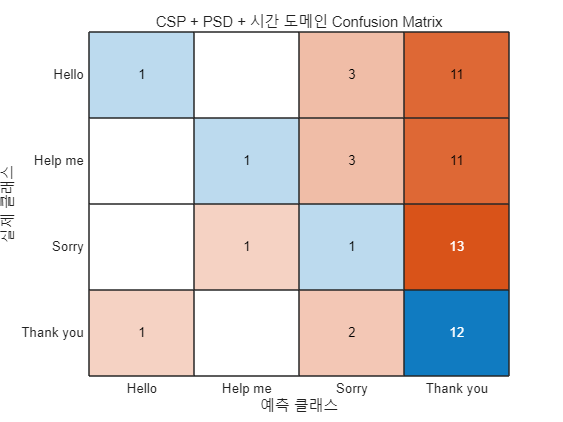


%% 10. Confusion Matrix 출력
predicted_labels = kfoldPredict(cv);
conf_mat = confusionmat(label_vector_num, predicted_labels);
conf_chart = confusionchart(conf_mat, label_classes);
title('CSP + PSD + 시간 도메인 Confusion Matrix');